# **Getting Started with Portfolio Optimization**

Copyright 2017 The MathWorks, Inc.

## **Portfolio Optimization**

This example is based on daily prices from dowPortfolio.xlsx that is shipped together with Financail Toolbox. To see the data, you can use `open('dowPortfolio.xlsx')` 

The main goal is to demonstrate how to calculate the optimal portfolio weights together with its risk and return.

T = readtable('dowPortfolio.xlsx')

T = 251×32 table
      Dates       DJI      AA       AIG      AXP      BA        C       CAT      DD       DIS      GE       GM       HD       HON      HPQ      IBM     INTC      JNJ      JPM      KO       MCD      MMM      MO       MRK     MSFT      PFE      PG        T       UTX      VZ       WMT      XOM 
    _________    _____    _____    _____    _____    

symbol = T.Properties.VariableNames(3:end)';
dailyReturn = tick2ret(T{:,3:end});
p = Portfolio('AssetList',symbol,'RiskFreeRate',0.01/252);
p = estimateAssetMoments(p, dailyReturn);
p = setDefaultConstraints(p); 
w1 = estimateMaxSharpeRatio(p)

w1 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.1648
    0.0000
    0.0461


[risk1, ret1] = estimatePortMoments(p, w1)

risk1 = 0.0068

ret1 = 0.0015

## **Data Visualization**

Plot the risk and expected return of all asset in the portfolio

f = figure;
tabgp = uitabgroup(f); % Define tab group
tab1 = uitab(tabgp,'Title','Efficient Frontier Plot'); % Create tab
ax = axes('Parent', tab1);
% Extract asset moments from portfolio and store in m and cov
[m, cov] = getAssetMoments(p); 
scatter(ax,sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.
xlabel('Risk')
ylabel('Expected Return')
text(sqrt(diag(cov))+0.0003,m,symbol,'FontSize',7); % Label ticker names

Plot optimal portfolio and efficient frontier using `plotFrontier`

hold on;
[risk2, ret2]  = plotFrontier(p,10);
plot(risk1,ret1,'p','markers',15,'MarkerEdgeColor','k',...
                'MarkerFaceColor','y');
hold off

Visualize table in MATLAB

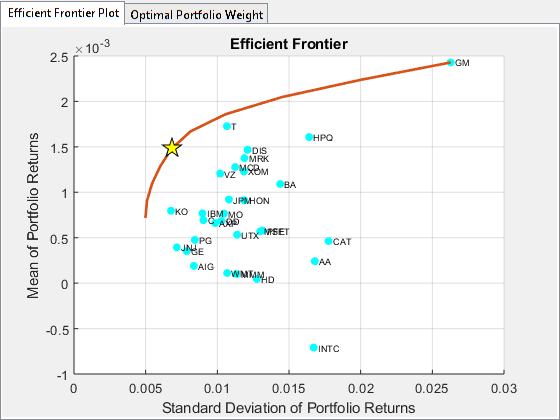

tab2 = uitab(tabgp,'Title','Optimal Portfolio Weight'); % Create tab

% Column names and column format
columnname = {'Ticker','Weight (%)'};
columnformat = {'char','numeric'};

% Define the data as a cell array
data = table2cell(table(symbol(w1>0),w1(w1>0)*100));

% Create the uitable
uit = uitable(tab2, 'Data', data,... 
            'ColumnName', columnname,...
            'ColumnFormat', columnformat,...
            'RowName',[]);

% Set width and height
uit.Position(3) = 450; % Widght
uit.Position(4) = 350; % Height